time6 = DYOErun31700120.AnalogChannels; 
signal6 = DYOErun31700120.VarName5; 
k = [time6,signal6]; 

% determine sampling frequency
Fs = 1 / mean(diff(time6));  % Sampling frequency in Hz



% analyze frequency components
Y = fft(signal6);
L = length(signal6);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);

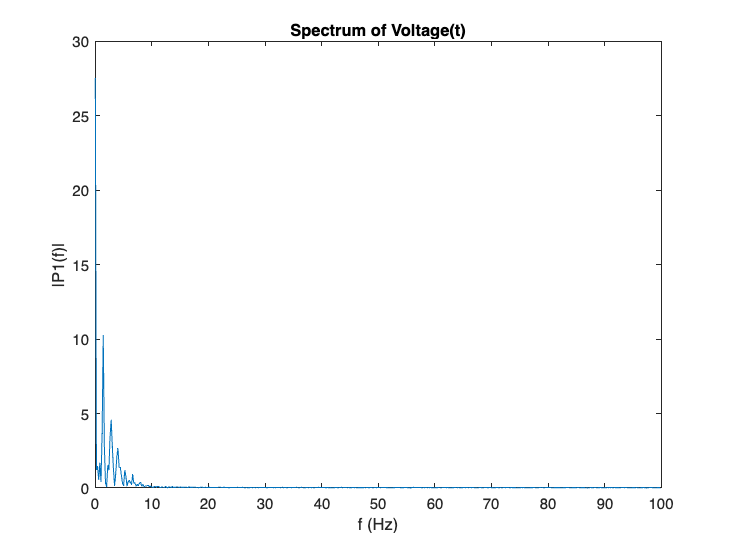

P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(L/2))/L;
plot(f, P1);
title('Spectrum of Voltage(t)');
xlabel('f (Hz)');
ylabel('|P1(f)|');

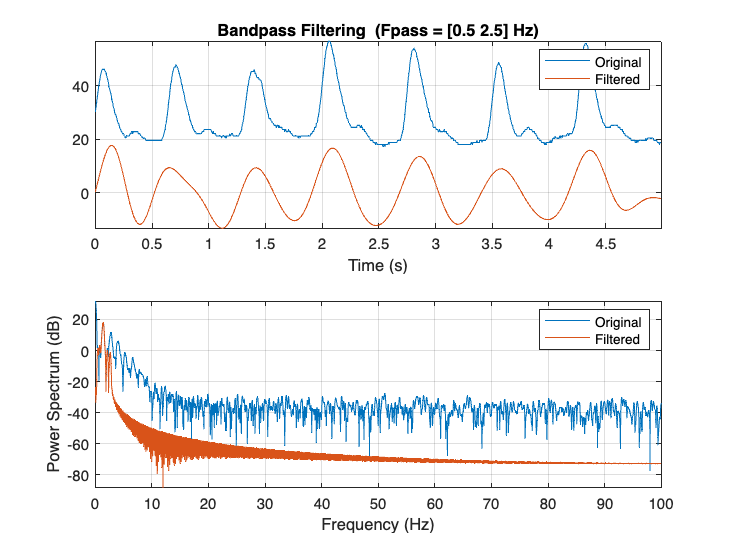

bandpass(signal6,[0.5 2.5],Fs)